## 0 - Imports

clear
clc
close all
format compact
cd('D:/Ivan/OneDrive/Projetos/Códigos ( Profissional )/Material criado/ICE/Proj_BSc_Hippocampus_Delta_Analysis');
addpath('Rotinas/Functions/');
srate=1250;
dt=1/srate;

## 1 - Pre Process

Load target attributes and filter noise

Track: eeg, speed_MMsec, lapID

Laps: WhlSpeedCCW, WhlSpeedCW

Spike: cluu, res

Clu: isIntern

% 1 - Load and filter files

% Files source path
dbPathOne = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part1~/';
dbPathTwo = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/dryad/Wang_et_al_eLife2016_data_part2~/';

% List of paths
filePaths = [dbPathOne; dbPathTwo];

% Pwelch - Specifications
WindowLength = 1*srate;
Overlap      = 0.9*srate;
NFFT         = 2^13;

order = [0; 1];
tittles = "All_Combined";
wSpeed = 100;
mSpeed = 100;

savePath = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/Processed/Single Files/';

processFiles = 0;
% Load files
if processFiles
    for i=1:size(filePaths,1)
        % List all files in each directory
        absolutFilePath = ls(fullfile(filePaths(i,1:end), '*.mat'));
        % Get the number of files
        [numFil, ~ ] = size(absolutFilePath);

        % Load each .mat in the structure
        for j=1:numFil
            dataSingle = load(strcat(filePaths(i,1:end),absolutFilePath(j, 1:end)), 'Track', 'Laps', 'Clu', 'Spike');

            trackNames = fieldnames(dataSingle.Track);
            trackNames(find(strcmp(trackNames, 'eeg'))) = [];
            trackNames(find(strcmp(trackNames, 'speed_MMsec'))) = [];
            trackNames(find(strcmp(trackNames, 'lapID'))) = [];
            trackNames(find(strcmp(trackNames, 'corrChoice'))) = [];
            lapsNames = fieldnames(dataSingle.Laps);
            lapsNames(find(strcmp(lapsNames, 'WhlSpeedCW'))) = [];
            lapsNames(find(strcmp(lapsNames, 'NLapCW'))) = [];
            spikeNames = fieldnames(dataSingle.Spike);
            spikeNames(find(strcmp(spikeNames, 'totclu'))) = [];
            spikeNames(find(strcmp(spikeNames, 'speed_MMsec'))) = [];
            spikeNames(find(strcmp(spikeNames, 'whlSpeed'))) = [];
            spikeNames(find(strcmp(spikeNames, 'res'))) = [];
            cluNames = fieldnames(dataSingle.Clu);
            cluNames(find(strcmp(cluNames, 'isIntern'))) = [];

            dataSingle.Track = rmfield(dataSingle.Track,trackNames);
            dataSingle.Laps = rmfield(dataSingle.Laps,lapsNames);        
            dataSingle.Spike = rmfield(dataSingle.Spike,spikeNames);  
            dataSingle.Clu = rmfield(dataSingle.Clu,cluNames);  
            dataSingle.Name = absolutFilePath(j, 1:16);

            dataSingle.Track.origEeg = dataSingle.Track.eeg;
            % Filter noise
            dataSingle = filterLFP(dataSingle, srate);

            % Process
            dataSingle = fillStruct(srate, WindowLength, Overlap, NFFT, dataSingle, wSpeed, mSpeed);

            Spike = dataSingle.Spike;
            Name = dataSingle.Name;
            Clu = dataSingle.Clu;  
            Lfp = dataSingle.Lfp;
            Delta = dataSingle.Delta;
            Theta = dataSingle.Theta;
            Choice = dataSingle.Choice;
            Speed = dataSingle.Speed;
            Pwelch = dataSingle.Pwelch;
            
            % Save
            mmtTtl = 'Pre';
            if i == 2
                mmtTtl = 'Pos';
            end

            file = sprintf('%s%s/%s/%s.mat', savePath, tittles, mmtTtl, Name);
            save(file, 'Clu', 'Spike', 'Name', 'Pwelch', 'Lfp', 'Delta', 'Theta', ...
               'Choice', 'Speed', '-v7.3')  

            sprintf('Dir: %d, File: %d', i, j)
        end
    end
end
clearvars -except srate dt Band Clu Name Spike

## 2 - Load processed file

% 2.0 - Load file
tic
clear
clc
close all
format compact
cd('D:/Ivan/OneDrive/Projetos/Códigos ( Profissional )/Material criado/ICE/Proj_BSc_Hippocampus_Delta_Analysis');
addpath('Rotinas/Functions/');
srate=1250;
dt=1/srate;

rootPath = 'D:/Ivan/Downloads/ProjetoWheelMaze/Dataset/Processed/Single Files/';
subPath = ["All_Combined"];
idx = 1;
loadPath = sprintf('%s%s/', rootPath, subPath(idx));

% Load files
dataFull = {};
% Load Pre
absolutFilePath = ls(fullfile(sprintf('%sPre/', loadPath), '*.mat'));
for file=1:size(absolutFilePath, 1)
    fileName = absolutFilePath(file, :);
    dataFull{1, file} = load(strcat(loadPath, 'Pre\', fileName));
    sprintf('%s - Pre - File: %d', subPath(idx), file)
end

ans = 'All_Combined - Pre - File: 1'

ans = 'All_Combined - Pre - File: 2'

ans = 'All_Combined - Pre - File: 3'

ans = 'All_Combined - Pre - File: 4'

ans = 'All_Combined - Pre - File: 5'

ans = 'All_Combined - Pre - File: 6'

ans = 'All_Combined - Pre - File: 7'

ans = 'All_Combined - Pre - File: 8'

ans = 'All_Combined - Pre - File: 9'

ans = 'All_Combined - Pre - File: 10'

% Load Pos
absolutFilePath = ls(fullfile(sprintf('%sPos/', loadPath), '*.mat'));
for file=1:size(absolutFilePath, 1)
    fileName = absolutFilePath(file, :);
    dataFull{2, file} = load(strcat(loadPath, 'Pos\', fileName));
    sprintf('%s - Pos - File: %d', subPath(idx), file)
end

ans = 'All_Combined - Pos - File: 1'

ans = 'All_Combined - Pos - File: 2'

ans = 'All_Combined - Pos - File: 3'

ans = 'All_Combined - Pos - File: 4'

ans = 'All_Combined - Pos - File: 5'

ans = 'All_Combined - Pos - File: 6'

ans = 'All_Combined - Pos - File: 7'

ans = 'All_Combined - Pos - File: 8'

ans = 'All_Combined - Pos - File: 9'

ans = 'All_Combined - Pos - File: 10'

[numReads, numSubReads ] = size(dataFull);
clearvars -except dataFull srate dt numReads numSubReads 
toc

Elapsed time is 39.010039 seconds.


## 3 - Analyse - Calc

% 3.1 - Error proportion
prop = {};
prop{1}.Hit = [];
prop{1}.Err = [];
prop{2}.Hit = [];
prop{2}.Err = [];
save = 0;
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/';
[numReads, numSubReads] = size(dataFull);

if save
    fileID = fopen(strcat(savePath,'Individual_hits_proportion.txt'), 'w');
else
    fileID = '';
end

for nData=1:numReads
    key = "Pre";
    if nData == 2
        key = "Pos";
    end
    sprintf('%s', key)
    
    if save
        fprintf(fileID, '\n');
    end
    
    for i=1:numSubReads
        
        dataTemp = dataFull{nData, i};
        choice = dataTemp.Choice;
        
        [count, value] = groupcounts(choice);
        
        if length(value) == 1
            if value == 0
                count = [count, 0];
                value = [value, 1];
            else
                count = [0, count];
                value = [0, value];
            end
        end
        err = (count(1)/sum(count))*100;
        hit = (count(2)/sum(count))*100;
        
        temp = sprintf('%s: Hits Freq: %i/%i = %.2f - Miss Freq: %i/%i = %.2f\n', dataTemp.Name(1:13), count(2), sum(count), hit, count(1), sum(count), err)
        fprintf(fileID, temp);
        prop{nData}.Hit = [prop{nData}.Hit; hit];
        prop{nData}.Err = [prop{nData}.Err; err];
        
    end
end

ans = 'Pre'

temp =     'A498-20120807: Hits Freq: 30/33 = 90.91 - Miss Freq: 3/33 = 9.09
     '

temp =     'A498-20120809: Hits Freq: 30/30 = 100.00 - Miss Freq: 0/30 = 0.00
     '

temp =     'A498-20120813: Hits Freq: 30/32 = 93.75 - Miss Freq: 2/32 = 6.25
     '

temp =     'A498-20120815: Hits Freq: 30/31 = 96.77 - Miss Freq: 1/31 = 3.23
     '

temp =     'A498-20120827: Hits Freq: 30/30 = 100.00 - Miss Freq: 0/30 = 0.00
     '

temp =     'A543-20120412: Hits Freq: 20/20 = 100.00 - Miss Freq: 0/20 = 0.00
     '

temp =     'A543-20120425: Hits Freq: 24/27 = 88.89 - Miss Freq: 3/27 = 11.11
     '

temp =     'A943-20120521: Hits Freq: 30/33 = 90.91 - Miss Freq: 3/33 = 9.09
     '

temp =     'A943-20120523: Hits Freq: 30/31 = 96.77 - Miss Freq: 1/31 = 3.23
     '

temp =     'A943-20120526: Hits Freq: 32/37 = 86.49 - Miss Freq: 5/37 = 13.51
     '

ans = 'Pos'

temp =     'A498-20120807: Hits Freq: 31/53 = 58.49 - Miss Freq: 22/53 = 41.51
     '

temp =     'A498-20120809: Hits Freq: 50/67 = 74.63 - Miss Freq: 17/67 = 25.37
     '

temp =     'A498-20120813: Hits Freq: 9/44 = 20.45 - Miss Freq: 35/44 = 79.55
     '

temp =     'A498-20120815: Hits Freq: 50/69 = 72.46 - Miss Freq: 19/69 = 27.54
     '

temp =     'A498-20120827: Hits Freq: 24/50 = 48.00 - Miss Freq: 26/50 = 52.00
     '

temp =     'A543-20120412: Hits Freq: 12/14 = 85.71 - Miss Freq: 2/14 = 14.29
     '

temp =     'A543-20120425: Hits Freq: 9/20 = 45.00 - Miss Freq: 11/20 = 55.00
     '

temp =     'A943-20120521: Hits Freq: 32/48 = 66.67 - Miss Freq: 16/48 = 33.33
     '

temp =     'A943-20120523: Hits Freq: 38/63 = 60.32 - Miss Freq: 25/63 = 39.68
     '

temp =     'A943-20120526: Hits Freq: 47/73 = 64.38 - Miss Freq: 26/73 = 35.62
     '

if save
    fclose(fileID)
end
clearvars -except dataFull srate dt dataLineCount numReads numSubReads savePath prop

### 3.1.1 Plot proportion - BarPlot - Fig X

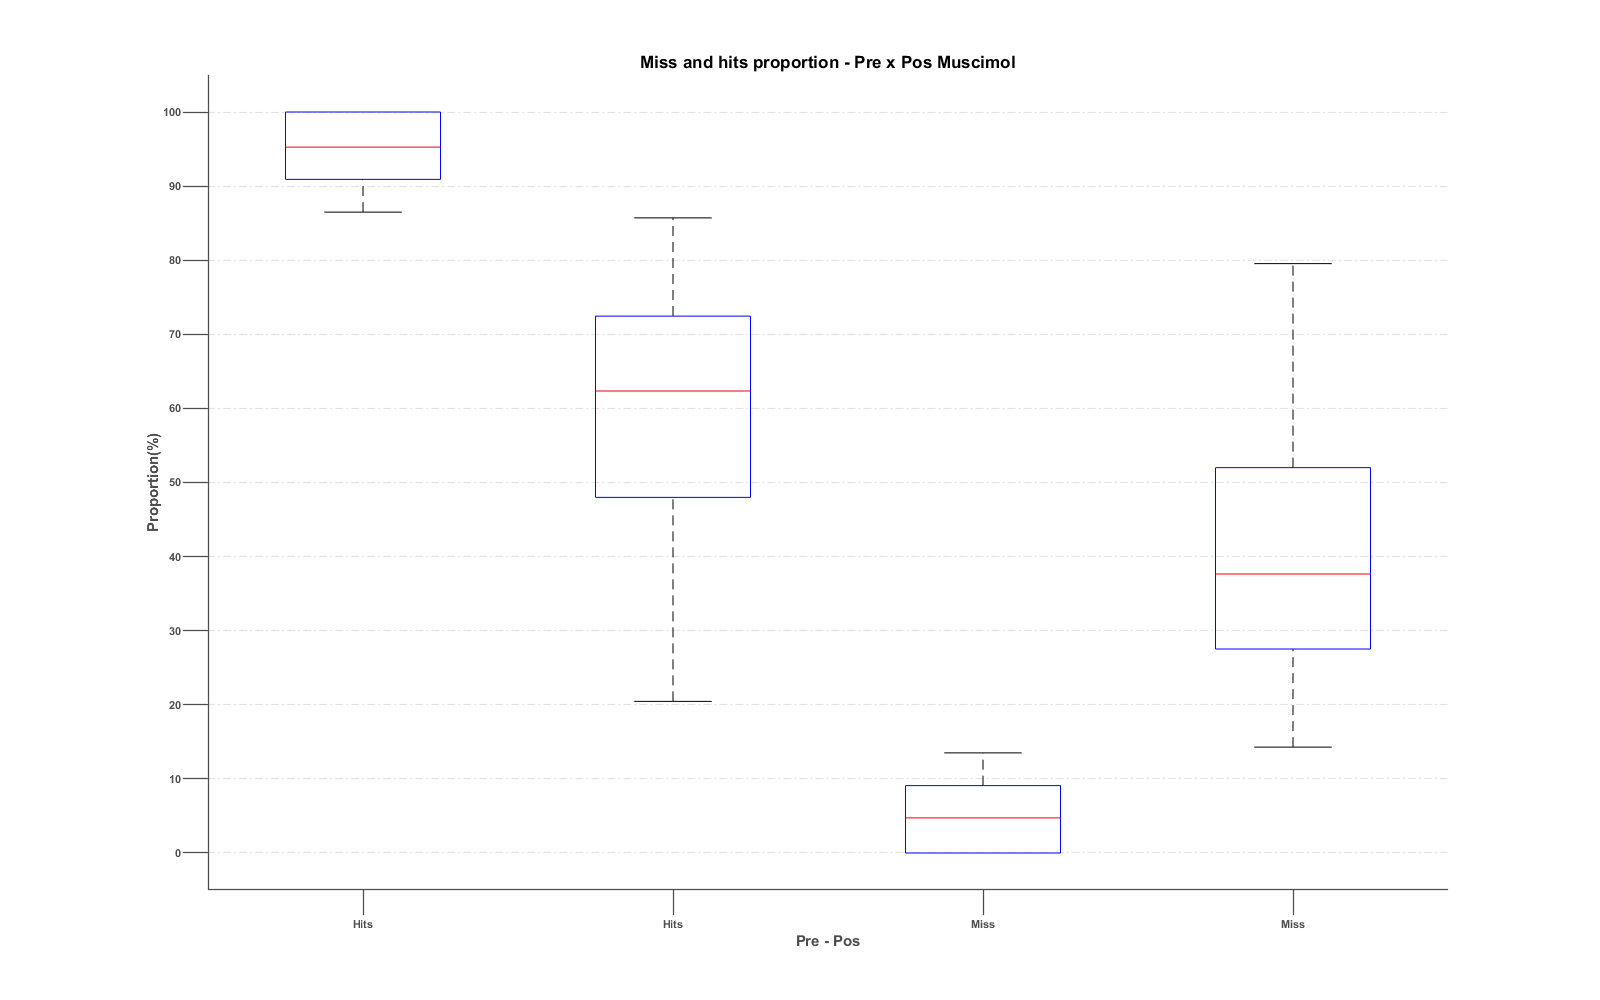

% Save path for results 
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/';

save = 0;
fig = figure(1);
fig.Position = [1 1 1600 1000];
boxplot([prop{1}.Hit, prop{2}.Hit, prop{1}.Err, prop{2}.Err] )

xticklabels(["Hits","Hits","Miss","Miss"])
xlabel("Pre - Pos")
ylabel("Proportion(%)")
title("Miss and hits proportion - Pre x Pos Muscimol")
% Aesthetics
set(gca, ...
    'Box',      'off',...
    'FontName', 'Helvetica',...
    'TickDir',  'out', ...
    'TickLength', [.02 .02],...
    'YGrid',     'on',...
    'GridLineStyle', '-.',...
    'XColor',    [.3 .3 .3],...
    'YColor',    [.3 .3 .3],...
    'LineWidth', 1,...
    'FontSize', 8, ...
    'FontWeight', 'bold',...
    'TitleFontSizeMultiplier', 1.6,...
    'LabelFontSizeMultiplier', 1.4,...
    'XScale', 'linear') 

if save
    fileName = char(strcat(savePath, 'Miss_n_hits_proportion'));
    saveas(fig,fileName, 'epsc');
    saveas(fig,fileName, 'png');
end
clearvars -except dataFull srate dt dataLineCount numReads numSubReads savePath prop

### 3.1.2 - Load each pwelch array and concat each session - Print

% Save results boolean, 1: YES, 0: NO
save = 0;
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/';

if save
    fileID = fopen(strcat(savePath,'Trial_statistics.txt'), 'w');
else
    fileID = '';
end
bands = [3,5];
for nData=1:numReads   
    pHits = [];
    pMiss = [];
    for i=1:numSubReads
        dataTemp = dataFull{nData, i}.Pwelch;
        fCols = (dataTemp.Frequency >= bands(1)) & (dataTemp.Frequency <= bands(2) );
        cTrials = logical(dataTemp.Choice);
   
        auxHitMz = dataTemp.Psd.Mz(cTrials, fCols);
        auxMisMz = dataTemp.Psd.Mz(~cTrials, fCols);
        auxHitWh = dataTemp.Psd.Wh(cTrials, fCols);
        auxMisWh = dataTemp.Psd.Wh(~cTrials, fCols);
        pHits = [pHits, reshape(auxHitMz, [1, prod(size(auxHitMz))])];
        pMiss = [pMiss, reshape(auxMisMz, [1, prod(size(auxMisMz))])];
        pHits = [pHits, reshape(auxHitWh, [1, prod(size(auxHitWh))])];
        pMiss = [pMiss, reshape(auxMisWh, [1, prod(size(auxMisWh))])];

    end
    key = "Pre";
    if nData == 2
        key = "Pos";
    end
    perc = printStats(pHits, pMiss, bands,strcat(key, ' - Hits x Miss'));
    pppSave(perc, save, fileID);

end

Undefined function or variable 'printStats'.

if save
    fclose(fileID)
end
clearvars -except dataFull data srate dt numReads numSubReads savePath 

### 3.1.3 Process Max power, max freq, speed - Calc

% Create a structure and save all values in

lOne = struct("Wh", [], "Mz", []);
lTwo = struct("MaxPower", lOne, "MaxFreq", lOne, "Speed", lOne, "Choice", []);
lThr = repmat(lTwo, 10,1);
data = {lThr, lThr};

wSpeed = 100;
mSpeed = 100;

bands = [3,5];
for nData=1:numReads   
    pHits = [];
    pMiss = [];
    for i=1:numSubReads
        dataTemp = dataFull{nData, i}.Pwelch;
        fMask = (dataTemp.Frequency >= bands(1)) & (dataTemp.Frequency <= bands(2) );
        
        speedMz = dataTemp.Speed.Mz;
        speedWh = dataTemp.Speed.Wh;

        [mzVal, mzIdx] = max(dataTemp.Psd.Mz(:, fMask)');
                
        data{nData}(i).MaxPower.Mz = mzVal';        
        data{nData}(i).MaxFreq.Mz = dataTemp.Frequency(mzIdx)';           
        data{nData}(i).Speed.Mz = speedMz;               
        data{nData}(i).Choice = dataTemp.Choice;               

        [whVal, whIdx] = max(dataTemp.Psd.Wh(:, fMask)');

        data{nData}(i).MaxPower.Wh = whVal';        
        data{nData}(i).MaxFreq.Wh = dataTemp.Frequency(whIdx)';           
        data{nData}(i).Speed.Wh = speedWh;        
    end
end
clearvars -except dataFull data srate dt numReads numSubReads savePath

### 3.1.4 - Plot max power, max freq and speed - ScatterPLot - Fig X

clf
whS = [];
whP = [];
whF = [];
mzS = [];
mzP = [];
mzF = [];
save = 0;
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Max Power and Frequency/';
for chc=0:1
    ttl = "Wrong choice";
    if chc
        ttl = "Right choice";
    end
    
    for nData=1:numReads
        for i=1:numSubReads
        % Mask
        cMask = data{nData}(i).Choice == chc;
        
        whS = [whS; data{nData}(i).Speed.Wh(cMask)];
        whP = [whP; data{nData}(i).MaxPower.Wh(cMask)];
        whF = [whF; data{nData}(i).MaxFreq.Wh(cMask)];
        mzS = [mzS; data{nData}(i).Speed.Mz(cMask)];
        mzP = [mzP; data{nData}(i).MaxPower.Mz(cMask)];
        mzF = [mzF; data{nData}(i).MaxFreq.Mz(cMask)];

        end
        % Pre x Pos   
        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        tittle = sprintf('Maze Max Power - %s\nMaze', ttl);
        fig = plotMaxPFS(nData, 2, 2, 1, mzS, mzP, 'k.', 'Speed', 'Max Power', tittle);
        
        tittle = sprintf('Wheel Max Power - %s\nWheel', ttl);
        fig = plotMaxPFS(nData, 2, 2, 2, whS, whP, 'r.', 'Speed', 'Max Power', tittle);
        
        tittle = sprintf('Maze Max Frequency - %s\nMaze', ttl);
        fig = plotMaxPFS(nData, 2, 2, 3, mzS, mzF, 'k.', 'Speed', 'Max Frequency', tittle);
        
        tittle = sprintf('Wheel Max Frequency- %s\nWheel', ttl);
        fig = plotMaxPFS(nData, 2, 2, 4, whS, whF, 'r.', 'Speed', 'Max Frequency', tittle);
       
        if save
            fileName = sprintf('%sMax_Power_n_Frequency_%s_%i',savePath, key, chc);
            saveas(fig,fileName, 'epsc');
            saveas(fig,fileName, 'png');
        end
    end
end
clearvars -except dataFull data srate dt numReads numSubReads savePath

### 3.1.5 - Max Power and Max Frequency analytics - All_Trials_Rank_n_Ttest - Print

save = 0;
for chc=0:1
    mzPreFreq = struct('List', [], 'Name', 'Frequency', 'Key', 'Pre', 'Job', 'Mz');
    mzPrePowe = struct('List', [], 'Name', 'Power', 'Key', 'Pre', 'Job', 'Mz');
    whPreFreq = struct('List', [], 'Name', 'Frequency', 'Key', 'Pre', 'Job', 'Wh');
    whPrePowe = struct('List', [], 'Name', 'Power', 'Key', 'Pre', 'Job', 'Wh');
    mzPosFreq = struct('List', [], 'Name', 'Frequency', 'Key', 'Pos', 'Job', 'Mz');
    mzPosPowe = struct('List', [], 'Name', 'Power', 'Key', 'Pos', 'Job', 'Mz');
    whPosFreq = struct('List', [], 'Name', 'Frequency', 'Key', 'Pos', 'Job', 'Wh');
    whPosPowe = struct('List', [], 'Name', 'Power', 'Key', 'Pos', 'Job', 'Wh');

    for i=1:numSubReads
        % Mask
        preCMask = data{1}(i).Choice == chc;
        posCMask = data{2}(i).Choice == chc;
        
        mzPreFreq.List = [mzPreFreq.List; data{1}(i).MaxFreq.Mz(preCMask)];
        mzPrePowe.List = [mzPrePowe.List; data{1}(i).MaxPower.Mz(preCMask)];
        whPreFreq.List = [whPreFreq.List; data{1}(i).MaxFreq.Wh(preCMask)];
        whPrePowe.List = [whPrePowe.List; data{1}(i).MaxPower.Wh(preCMask)];
        mzPosFreq.List = [mzPosFreq.List; data{2}(i).MaxFreq.Mz(posCMask)];
        mzPosPowe.List = [mzPosPowe.List; data{2}(i).MaxPower.Mz(posCMask)];
        whPosFreq.List = [whPosFreq.List; data{2}(i).MaxFreq.Wh(posCMask)];
        whPosPowe.List = [whPosPowe.List; data{2}(i).MaxPower.Wh(posCMask)];
    end

    combined = nchoosek({mzPreFreq, mzPrePowe, whPreFreq, whPrePowe, ...
        mzPosFreq, mzPosPowe, whPosFreq, whPosPowe}, 2);

    savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/';

    if save
        fileID = fopen(sprintf('%sAll_Trials_Rank_n_Ttest_%i.txt', savePath, chc), 'w');
    else
        fileID = '';
    end
    for i=1:size(combined,1)
        left = combined{i,1};
        right = combined{i,2};
        aux = sprintf('\nMax %s x Max %s - %s x %s - %s x %s', left.Name, right.Name, left.Key, right.Key, left.Job, right.Job);
        perc = printStats(left.List, right.List, [3,5], aux);
        pppSave(perc, save, fileID);
    end
    if save
        fclose(fileID)
    end
end
clearvars -except dataFull data srate dt numReads numSubReads savePath

###  3.1.6 - Group PSD + std - Lineplot - Fig 1

clc
save = 0;
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/PSD_Group/';
for chc=0:1
    clf
    
    ttl = "Wrong choice";
    if chc
        ttl = "Right choice";
    end
    data = {struct('Mz', [], 'Wh', []), struct('Mz', [], 'Wh', [])}; 
    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            dataTemp = dataFull{nData, i}.Pwelch;

            mzPsd = [];
            mzFrq = [];
            whPsd = [];
            whFrq = [];
       
            cMask = dataTemp.Choice == chc;
            
            data{nData}.Mz = [data{nData}.Mz; dataTemp.Psd.Mz(cMask, :)];
            data{nData}.Wh = [data{nData}.Wh; dataTemp.Psd.Wh(cMask, :)];
        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        fig = figure(1);
        fig.Position = [1 1 1600 1000];
        subplot(1,2,nData);

        x = dataTemp.Frequency;
        meanWh = mean(data{nData}.Wh);
        meanMz = mean(data{nData}.Mz);
        % Std  
        stdWh = std(data{nData}.Wh)/sqrt(nTrials); 
        stdMz = std(data{nData}.Mz)/sqrt(nTrials);

        plot(x, meanWh, 'r', x, meanMz, 'k')
        hold on
        plot(x, meanMz+stdMz, 'k--', x, meanMz-stdMz, 'k--')
        plot(x, meanWh+stdWh, 'r--', x, meanWh-stdWh, 'r--')
        xlim([0,12])
        ylim([0 , 50000])
        label1{1} = 'Wheel';
        label1{2} = 'Maze';
        box off
        legend(label1,'location','bestoutside','orientation','horizontal')
        legend('boxoff')
        ylabel('Power')
        xlabel('Frequency(Hz)')
        title(sprintf("Mean PSD - %s\n%s", key, ttl))
        set(gca, ...
        'Box',      'off',...
        'FontName', 'Arial',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    end

    if save
        fileName = sprintf('%sGroup_PSD_Pre_Pro_Std_%i',savePath, chc);
        saveas(fig,fileName, 'epsc');
        saveas(fig,fileName, 'png');
    end
end

clearvars -except dataFull data srate dt numReads numSubReads savePath


### 3.1.7 - Group PSD + std - All 4 - Mz n Wh - Correct x Miss - Fig X

clc
save = 0;
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/PSD_Group/';

for nData=1:numReads
    data = {struct('Mz', [], 'Wh', [], 'nTrials' , 0), struct('Mz', [], 'Wh', [], 'nTrials' , 0)}; 

    for chc=1:2
        for i=1:numSubReads
            data{chc}.nTrials = data{chc}.nTrials + sum(dataFull{nData, i}.Choice == chc-1);
            
            dataTemp = dataFull{nData, i}.Pwelch;

            cMask = dataTemp.Choice == chc-1;

            data{chc}.Wh = [data{chc}.Wh; dataTemp.Psd.Wh(cMask, :)];
            data{chc}.Mz = [data{chc}.Mz; dataTemp.Psd.Mz(cMask, :)];
        end
        
        meanWh = mean(data{chc}.Wh);
        meanMz = mean(data{chc}.Mz);
        % Std  
        stdWh = std(data{chc}.Wh)/sqrt(data{chc}.nTrials); 
        stdMz = std(data{chc}.Mz)/sqrt(data{chc}.nTrials);
        
    end
    
    key = "Pre";
    fIdx = 0;
    if nData == 2
        key = "Pos";
        fIdx = 2;
    end
    
    % All 4 Pre x Pos - Mz N Wheel 
    x = dataTemp.Frequency;
    fig = figure(1);
    fig.Position = [1 1 1600 1000];
    
    plotPSDWhxMz(1+fIdx, x, data{1}.Wh, data{2}.Wh, data{1}.nTrials, data{2}.nTrials, ["Wheel Wrong", "Wheel Correct"], key);
    plotPSDWhxMz(2+fIdx, x, data{1}.Mz, data{2}.Mz, data{1}.nTrials, data{2}.nTrials, ["Maze Wrong", "Maze Correct"], key);
end

if save
    fileName = sprintf('%sGroup_PSD_Pre_Pos_all_Std',savePath);
    saveas(fig,fileName, 'epsc');
    saveas(fig,fileName, 'png');
end

### 3.1.8 - err bar Corr x Miss - Barplot - Fig X


clf
save = 0;
bands = [3,5; 6,10];
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Bar/';
for bnd=1:length(bands)
    data = {struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', []), struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', [])}; 
   
%     clf;
    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsdC = [];
            mzPsdE = [];
            frq = [];
            whPsdC = [];
            whPsdE = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));
            cMask = dataTemp.Choice == 0;

            data{nData}.MzC = [data{nData}.MzC; dataTemp.Psd.Mz(~cMask, fMask)];
            data{nData}.WhC = [data{nData}.WhC; dataTemp.Psd.Wh(~cMask, fMask)];
            data{nData}.MzE = [data{nData}.MzE; dataTemp.Psd.Mz(cMask, fMask)];
            data{nData}.WhE = [data{nData}.WhE; dataTemp.Psd.Wh(cMask, fMask)];

        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        fig = figure(bnd);
        fig.Position = [1 1 1600 1000];
        subplot(1,2,nData);

        x = mean(data{nData}.Freq, 2);
        meanWhC = mean(data{nData}.WhC,2);
        meanMzC = mean(data{nData}.MzC,2);
        meanWhE = mean(data{nData}.WhE,2);
        meanMzE = mean(data{nData}.MzE,2);

        % Std  
        stdWhC = std(meanWhC)/sqrt(nTrials);
        stdMzC = std(meanMzC)/sqrt(nTrials);
        stdWhE = std(meanWhE)/sqrt(nTrials);
        stdMzE = std(meanMzE)/sqrt(nTrials);

        bar([1,2,3,4], [mean(meanMzC), mean(meanMzE), mean(meanWhC), mean(meanWhE)], 'w')
        [h, p, w] = swtest([meanMzC; meanMzE]);
        
        if h == 1
            [ pMz, hMz ] = ranksum(meanMzC, meanMzE);
        else
            [ hMz, pMz ] = ttest2(meanMzC, meanMzE);
        end
        [h, p, w] = swtest([meanWhC; meanWhE]);
        if h == 1
            [ pWh, hWh ] = ranksum(meanWhC, meanWhE);
        else
            [ hWh, pWh ] = ttest2(meanWhC, meanWhE);
        end
        
        hold on
        errorbar([1,2,3,4], [mean(meanMzC), mean(meanMzE), mean(meanWhC), mean(meanWhE)], [stdMzC, stdMzE, stdWhC, stdWhE], 'k.')
        box off
        xticklabels(["Maze C", "Maze E", "Wheel C", "Wheel E"])
        ylim([0,25000])
        if bnd == 1
            ylim([0,15000])
        end
        ylabel('Power')
        title(sprintf("Mean PSD - %s - Band: %i - %i Hz\nMaze: h: %f p: %f\nWheel: h: %f p: %f", key, bands(bnd,1), bands(bnd,2), hMz, pMz, hWh, pWh))
        set(gca, ...
        'Box',      'off',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    end


    if save
        fileName = sprintf('%sGroup_Bar_PSD_Pre_Pro_Std_%i_%i',savePath, bands(bnd,1), bands(bnd,2));
        saveas(fig,fileName, 'epsc');
        saveas(fig,fileName, 'png');
    end
end
clearvars -except dataFull data srate dt numReads numSubReads savePath
%% 3.1.9 - Boxplot Delta x Theta - Fig 1

clf
save = 0;
bands = [3,5; 6,10];
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Box/';
for bnd=1:length(bands)
    data = {struct('Mz', [], 'Wh', [], 'Freq', []), struct('Mz', [], 'Wh', [], 'Freq', [])}; 
    clf;
    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsd = [];
            frq = [];
            whPsd = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));

            data{nData}.Mz = [data{nData}.Mz; dataTemp.Psd.Mz(:, fMask)];
            data{nData}.Wh = [data{nData}.Wh; dataTemp.Psd.Wh(:, fMask)];
        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        fig = figure(1);
        fig.Position = [1 1 1600 1000];
        subplot(1,2,nData);

%         x = mean(data{nData}.Freq, 2);
        meanMz = mean(data{nData}.Mz,2);
        meanWh = mean(data{nData}.Wh,2);

        boxplot([meanMz, meanWh])
        p_norm = swtest([meanMz;meanMz]);
        if p_norm == 1
            [ hMz, pMz ] = signrank(meanMz, meanMz);
            [ hWh, pWh ] = signrank(meanWh, meanWh);
        else
            [ hMz, pMz ] = ttest2(meanMz, meanMz);
            [ hWh, pWh ] = ttest2(meanWh, meanWh);
        end

        hold on
        box off
        xticklabels(["Maze", "Wheel"])
        ylabel('Power (mV²/Hz)')
        title(sprintf("Mean PSD - %s - Band: %i - %i Hz\nMaze: h: %f p: %f\nWheel: h: %f p: %f", key, bands(bnd,1), bands(bnd,2), hMz, pMz, hWh, pWh))
        set(gca, ...
        'Box',      'off',...
        'FontName', 'Arial',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    end


    if save
        fileName = sprintf('%sGroup_Box_PSD_Pre_Pos_Std_%i_%i',savePath, bands(bnd,1), bands(bnd,2));
        saveas(fig,fileName, 'epsc');
        saveas(fig,fileName, 'png');
    end
end
clearvars -except dataFull data srate dt numReads numSubReads savePath
%% 3.1.9 - Histogram Corr x Miss - POWER - Fig X

clf
save = 0;
bands = [3,5; 6,10];
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Bar/';
for bnd=2%:length(bands)
    data = {struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', []), struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', [])}; 
    
    clf;
    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsdC = [];
            mzPsdE = [];
            frq = [];
            whPsdC = [];
            whPsdE = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));
            cMask = dataTemp.Choice == 0;

            data{nData}.MzC = [data{nData}.MzC; dataTemp.Psd.Mz(~cMask, fMask)];
            data{nData}.WhC = [data{nData}.WhC; dataTemp.Psd.Wh(~cMask, fMask)];
            data{nData}.MzE = [data{nData}.MzE; dataTemp.Psd.Mz(cMask, fMask)];
            data{nData}.WhE = [data{nData}.WhE; dataTemp.Psd.Wh(cMask, fMask)];

        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        fig = figure(1);
        fig.Position = [1 1 1600 1000];
        subplot(1,2,nData);

        x = mean(data{nData}.Freq, 2);
        meanWhC = mean(data{nData}.WhC,2);
        meanMzC = mean(data{nData}.MzC,2);
        meanWhE = mean(data{nData}.WhE,2);
        meanMzE = mean(data{nData}.MzE,2);

        % Std  
        stdWhC = std(meanWhC)/sqrt(nTrials);
        stdMzC = std(meanMzC)/sqrt(nTrials);
        stdWhE = std(meanWhE)/sqrt(nTrials);
        stdMzE = std(meanMzE)/sqrt(nTrials);
        
        bns = [0:700:15000];
        if bnd == 2
            bns = [0:1500:35000];
        end

        histogram(meanWhC,bns, 'FaceColor',[0 1 0] )
        hold on
        histogram(meanWhE,bns,'FaceColor',[0 0 1])
        [h, p, w] = swtest([meanWhC; meanWhE]);
        
        if h == 1
            [ pMz, hMz ] = ranksum(meanMzC, meanMzE);
        else
            [ hMz, pMz ] = ttest2(meanMzC, meanMzE);
        end
        [h, p, w] = swtest([meanWhC; meanWhE]);
        if h == 1
            [ pWh, hWh ] = ranksum(meanWhC, meanWhE);
        else
            [ hWh, pWh ] = ttest2(meanWhC, meanWhE);
        end
        
        box off
        label1{1} = 'Correct';
        label1{2} = 'Miss';
        box off
        legend(label1,'location','bestoutside','orientation','horizontal')
        ylabel('Power')
        title(sprintf("Mean PSD - %s - Band: %i - %i Hz\nMaze: h: %f p: %f\nWheel: h: %f p: %f", key, bands(bnd,1), bands(bnd,2), hMz, pMz, hWh, pWh))
        axis square
        set(gca, ...
        'Box',      'off',...
        'FontName', 'Arial',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    end


    if save
        fileName = sprintf('%sGroup_Histogram_PSD_Pre_Pos_%i_%i',savePath, bands(bnd,1), bands(bnd,2));
        saveas(fig,fileName, 'svg');
        saveas(fig,fileName, 'png');
    end
end
% clearvars -except dataFull data srate dt numReads numSubReads savePath
%% 3.1.10 - Histogram Corr x Miss - PEAK Freq - Fig X
clf
save = 0;
bands = [3,5; 6,10];
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Bar/';
for bnd=1:length(bands)
    data = {struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', []), struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', [])}; 
   
    clf;
    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsdC = [];
            mzPsdE = [];
            frq = [];
            whPsdC = [];
            whPsdE = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));
            cMask = dataTemp.Choice == 0;

            data{nData}.MzC = [data{nData}.MzC; dataTemp.Psd.Mz(~cMask, fMask)];
            data{nData}.WhC = [data{nData}.WhC; dataTemp.Psd.Wh(~cMask, fMask)];
            data{nData}.MzE = [data{nData}.MzE; dataTemp.Psd.Mz(cMask, fMask)];
            data{nData}.WhE = [data{nData}.WhE; dataTemp.Psd.Wh(cMask, fMask)];


        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        fig = figure(1);
        fig.Position = [1 1 1600 1000];
        subplot(1,2,nData);

%         x = mean(data{nData}.Freq, 2);
        [maxLeft, idxWh] = max(data{nData}.WhC');
        aux = dataTemp.Frequency(fMask);
        peakWhC = aux(idxWh);
%         [maxLeft, idxMz] = max(data{nData}.MzC');
%         aux = dataTemp.Frequency(fMask);
%         peakMzC = aux(idxMz);
        [maxLeft, idxWh] = max(data{nData}.WhE');
        aux = dataTemp.Frequency(fMask);
        peakWhE = aux(idxWh);
%         [maxLeft, idxMz] = max(data{nData}.MzE');
%         aux = dataTemp.Frequency(fMask);
%         peakMzE = aux(idxMz);

        % Std  
%         stdWhC = std(meanWhC)/sqrt(nTrials);
%         stdMzC = std(meanMzC)/sqrt(nTrials);
%         stdWhE = std(meanWhE)/sqrt(nTrials);
%         stdMzE = std(meanMzE)/sqrt(nTrials);
        
        bns = [3:.15:5];
        if bnd == 2
            bns = [6:.35:10];
        end

        histogram(peakWhC,bns, 'FaceColor',[0 1 0] )
        hold on
        histogram(peakWhE,bns, 'FaceColor',[0 0 1])
        [h, p, w] = swtest([peakWhC, peakWhE]);
        
%         if h == 1
%             [ pMz, hMz ] = ranksum(meanMzC, meanMzE);
%         else
%             [ hMz, pMz ] = ttest2(meanMzC, meanMzE);
%         end
%         [h, p, w] = swtest([meanWhC; meanWhE]);
        if h == 1
            [ pWh, hWh ] = ranksum(peakWhC, peakWhE);
        else
            [ hWh, pWh ] = ttest2(peakWhC, peakWhE);
        end
        
        box off
        label1{1} = 'Correct';
        label1{2} = 'Miss';
        box off
        legend(label1,'location','bestoutside','orientation','horizontal')
        ylabel('Peak Freq')
        title(sprintf("Mean PSD - %s - Band: %i - %i Hz\nWheel: h: %f p: %f", key, bands(bnd,1), bands(bnd,2), hWh, pWh))
        axis square
        set(gca, ...
        'Box',      'off',...
        'FontName', 'Arial',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    end


    if save
        fileName = sprintf('%sGroup_Histogram_Peak_Freq_Pre_Pos_%i_%i',savePath, bands(bnd,1), bands(bnd,2));
        saveas(fig,fileName, 'svg');
        saveas(fig,fileName, 'png');
    end
end
clearvars -except dataFull data srate dt numReads numSubReads savePath

%% 3.1.11 - BoxPlot Corr x Miss - PEAK Freq - Fig X
clf
save = 0;
bands = [3,5; 6,10];
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Bar/';
for bnd=1:length(bands)
    data = {struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', []), struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', [])}; 
   
    clf;
    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsdC = [];
            mzPsdE = [];
            frq = [];
            whPsdC = [];
            whPsdE = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));
            cMask = dataTemp.Choice == 0;

            data{nData}.MzC = [data{nData}.MzC; dataTemp.Psd.Mz(~cMask, fMask)];
            data{nData}.WhC = [data{nData}.WhC; dataTemp.Psd.Wh(~cMask, fMask)];
            data{nData}.MzE = [data{nData}.MzE; dataTemp.Psd.Mz(cMask, fMask)];
            data{nData}.WhE = [data{nData}.WhE; dataTemp.Psd.Wh(cMask, fMask)];


        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        fig = figure(1);
        fig.Position = [1 1 1600 1000];
        subplot(1,2,nData);

        [maxLeft, idxWh] = max(data{nData}.WhC');
        aux = dataTemp.Frequency(fMask);
        peakWhC = aux(idxWh);

        [maxLeft, idxWh] = max(data{nData}.WhE');
        aux = dataTemp.Frequency(fMask);
        peakWhE = aux(idxWh);
        
        g1 = repmat({'Wheel Correct'},length(peakWhC),1);
        g2 = repmat({'Wheel Miss'},length(peakWhE),1);
        g = [g1; g2];
        boxplot([peakWhC, peakWhE], g)
        
        [h, p, w] = swtest([peakWhC, peakWhE]);
        if h == 1
            [ pWh, hWh ] = ranksum(peakWhC, peakWhE);
        else
            [ hWh, pWh ] = ttest2(peakWhC, peakWhE);
        end
        
        box off
%         label1{1} = 'Correct';
%         label1{2} = 'Miss';
%         legend(label1,'location','bestoutside','orientation','horizontal')
        ylabel('Peak Freq')
        title(sprintf("Mean PSD - %s - Band: %i - %i Hz\nWheel: h: %f p: %f", key, bands(bnd,1), bands(bnd,2), hWh, pWh))
        axis square
        set(gca, ...
        'Box',      'off',...
        'FontName', 'Arial',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    end


    if save
        fileName = sprintf('%sGroup_BoxPlot_Peak_Freq_Pre_Pos_%i_%i',savePath, bands(bnd,1), bands(bnd,2));
        saveas(fig,fileName, 'svg');
        saveas(fig,fileName, 'png');
    end
end
clearvars -except dataFull data srate dt numReads numSubReads savePath

%% 3.1.11 - BoxPlot Corr x Miss - Power - Fig X
clf
save = 0;
bands = [3,5; 6,10];
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Bar/';
for bnd=1:length(bands)
    data = {struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', []), struct('MzC', [], 'WhC', [], 'MzE', [], 'WhE', [], 'Freq', [])}; 
   
    clf;
    for nData=1:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsdC = [];
            mzPsdE = [];
            frq = [];
            whPsdC = [];
            whPsdE = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));
            cMask = dataTemp.Choice == 0;

            data{nData}.MzC = [data{nData}.MzC; dataTemp.Psd.Mz(~cMask, fMask)];
            data{nData}.WhC = [data{nData}.WhC; dataTemp.Psd.Wh(~cMask, fMask)];
            data{nData}.MzE = [data{nData}.MzE; dataTemp.Psd.Mz(cMask, fMask)];
            data{nData}.WhE = [data{nData}.WhE; dataTemp.Psd.Wh(cMask, fMask)];

        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        fig = figure(1);
        fig.Position = [1 1 1600 1000];
        subplot(1,2,nData);

        x = mean(data{nData}.Freq, 2);
        meanWhC = mean(data{nData}.WhC,2);
        meanMzC = mean(data{nData}.MzC,2);
        meanWhE = mean(data{nData}.WhE,2);
        meanMzE = mean(data{nData}.MzE,2);

        
        g1 = repmat({'Wheel Correct'},length(meanWhC),1);
        g2 = repmat({'Wheel Miss'},length(meanWhE),1);
        g = [g1; g2];
        boxplot([meanWhC; meanWhE], g)
        
        [h, p, w] = swtest([meanWhC; meanWhE]);
        if h == 1
            [ pWh, hWh ] = ranksum(meanWhC, meanWhE);
        else
            [ hWh, pWh ] = ttest2(meanWhC, meanWhE);
        end
        
        box off
        ylabel('Power')
        title(sprintf("Power - %s - Band: %i - %i Hz\nWheel: h: %f p: %f", key, bands(bnd,1), bands(bnd,2), hWh, pWh))
        axis square
        set(gca, ...
        'Box',      'off',...
        'FontName', 'Arial',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    end


    if save
        fileName = sprintf('%sGroup_BoxPlot_Power_Pre_Pos_%i_%i',savePath, bands(bnd,1), bands(bnd,2));
        saveas(fig,fileName, 'svg');
        saveas(fig,fileName, 'png');
    end
end
% clearvars -except dataFull data srate dt numReads numSubReads savePath


%% Stats peak freq Theta - Mz x Wh - Pre
clf
save = 0;
bands = [3,5; 6,10];
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Bar/';
for bnd=2%:length(bands)
    data = {struct('Mz', [], 'Wh', [],'Freq', []), struct('Mz', [], 'Wh', [], 'Freq', [])}; 
   
    for nData=1%:numReads
        nTrials = 0;
        for i=1:numSubReads
            dataTemp = dataFull{nData, i}.Pwelch;
            nTrials = nTrials + size(dataFull{nData, i}.Choice, 1);

            mzPsdC = [];
            mzPsdE = [];
            frq = [];

            fMask = ( dataTemp.Frequency  > bands(bnd,1) ) & ( dataTemp.Frequency  < bands(bnd,2));

            data{nData}.Mz = [data{nData}.Mz; dataTemp.Psd.Mz(:, fMask)];
            data{nData}.Wh = [data{nData}.Wh; dataTemp.Psd.Wh(:, fMask)];


        end

        key = "Pre";
        if nData == 2
            key = "Pos";
        end

        [maxLeft, idxMz] = max(data{nData}.Mz');
        aux = dataTemp.Frequency(fMask);
        peakMz = aux(idxMz);

        [maxLeft, idxWh] = max(data{nData}.Wh');
        aux = dataTemp.Frequency(fMask);
        peakWh = aux(idxWh);

        [h, p, w] = swtest([peakMz, peakWh]);
        
        if h == 1
            [ pWh, hWh ] = signrank(peakMz, peakWh);
        else
            [ hWh, pWh ] = ttest(peakMz, peakWh);
        end
        

    end

    sprintf( 'P-value: %.2e - H: %i', pWh, hWh)
end

%% 3.1.11 - Combined ACG - Imagesc - Fig 1 n 3

grIdx = [1, 2; 3, 4];
save = 0;
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/ACG/';

for nData=1:numReads
    auxMzAcgCombine = [];
    auxWhAcgCombine = [];
    for i=1:numSubReads
        dataTemp = dataFull{nData, i};
        
        laps = size(dataTemp.Choice, 1);
        for lp=1:laps

            mzMask = dataTemp.Speed.Mz{lp} > 100;
            whMask = dataTemp.Speed.Wh{lp} > 100;

            LFPMz = dataTemp.Lfp{lp}(mzMask);
            LFPWh = dataTemp.Lfp{lp}(whMask);

            % Capture snippet
            [acgMz, lagsMz] = xcorr(LFPMz,'coef', 500);    
            [acgWh, lagsWh] = xcorr(LFPWh,'coef', 500);    

            auxMzAcgCombine = [auxMzAcgCombine, acgMz];
            auxWhAcgCombine = [auxWhAcgCombine, acgWh];

            sprintf('%d %d %i',nData, i, lp)
        end
    end

    ttlKey = 'Pre';
    if nData == 2
        ttlKey = 'Pos';
    end

    % Plot
    fig = figure(1);
    fig.Position = [1 1 1600 1000];
    sgtitle('Trial Combined ACG LFP')
    yyaxis left
    plotImagesc(grIdx(nData, 1), lagsMz, auxMzAcgCombine', 'Mz', ttlKey)
    hold on
    val = size(auxMzAcgCombine, 1)/2;
    xLimValue = -val:val-1;
    
    yyaxis right
    plot(xLimValue, mean(auxMzAcgCombine, 2), 'w')
    yyaxis left
    plotImagesc(grIdx(nData, 2), lagsWh, auxWhAcgCombine', 'Wh', ttlKey)
    yyaxis right
    plot(xLimValue, mean(auxWhAcgCombine, 2), 'w')
end
if save
    fileName = sprintf('%sCombined_Trial_Imagesc_ACG_LFP', savePath);
    saveas(fig,fileName, 'epsc');
    saveas(fig,fileName, 'png');
end 

clearvars -except dataFull data srate dt numReads numSubReads savePath
%% 3.2.1 Figure 2 - Calc
speedthresh=100;
oneStep = struct("Mz", [], "Wh", []);
secStep = struct('Trial', oneStep, 'Full', oneStep);

savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/Max Power and Frequency/';
save = 1; 

for nData=1:numReads
    respDt = struct('Amp', secStep, 'Fre', secStep);
    respTh = struct('Amp', secStep, 'Fre', secStep);
    speed = secStep;
    
    for file=1:numSubReads
        dataTemp = dataFull{nData, file};
        
        for session=1:length(dataTemp.Choice)
            % Speed
            speedMzMask = dataTemp.Speed.Mz{session} > speedthresh;
            speedWhMask = dataTemp.Speed.Wh{session} > speedthresh;
            
            speed.Trial.Mz = [ speed.Trial.Mz, mean(dataTemp.Speed.Mz{session}(speedMzMask)) ];
            speed.Trial.Wh = [ speed.Trial.Wh, mean(dataTemp.Speed.Wh{session}(speedWhMask)) ];
            speed.Full.Mz = [ speed.Full.Mz; dataTemp.Speed.Mz{session}(speedMzMask) ];
            speed.Full.Wh = [ speed.Full.Wh; dataTemp.Speed.Wh{session}(speedWhMask) ];
            % Amplitude
            respDt.Amp.Trial.Mz = [respDt.Amp.Trial.Mz, mean(dataTemp.Delta.Amplitude{session}(speedMzMask)) ];
            respDt.Amp.Trial.Wh = [respDt.Amp.Trial.Wh, mean(dataTemp.Delta.Amplitude{session}(speedWhMask)) ];
            respTh.Amp.Trial.Mz = [respTh.Amp.Trial.Mz, mean(dataTemp.Theta.Amplitude{session}(speedMzMask)) ];
            respTh.Amp.Trial.Wh = [respTh.Amp.Trial.Wh, mean(dataTemp.Theta.Amplitude{session}(speedWhMask)) ];
            respDt.Amp.Full.Mz = [respDt.Amp.Full.Mz; dataTemp.Delta.Amplitude{session}(speedMzMask)' ];
            respDt.Amp.Full.Wh = [respDt.Amp.Full.Wh; dataTemp.Delta.Amplitude{session}(speedWhMask)' ];
            respTh.Amp.Full.Mz = [respTh.Amp.Full.Mz; dataTemp.Theta.Amplitude{session}(speedMzMask)' ];
            respTh.Amp.Full.Wh = [respTh.Amp.Full.Wh; dataTemp.Theta.Amplitude{session}(speedWhMask)' ];
            % Frequency
            respDt.Fre.Trial.Mz = [respDt.Fre.Trial.Mz, mean(dataTemp.Delta.InstFreq{session}(speedMzMask)) ];
            respDt.Fre.Trial.Wh = [respDt.Fre.Trial.Wh, mean(dataTemp.Delta.InstFreq{session}(speedWhMask)) ];
            respTh.Fre.Trial.Mz = [respTh.Fre.Trial.Mz, mean(dataTemp.Theta.InstFreq{session}(speedMzMask)) ];
            respTh.Fre.Trial.Wh = [respTh.Fre.Trial.Wh, mean(dataTemp.Theta.InstFreq{session}(speedWhMask)) ];
            respDt.Fre.Full.Mz = [respDt.Fre.Full.Mz; dataTemp.Delta.InstFreq{session}(speedMzMask)' ];
            respDt.Fre.Full.Wh = [respDt.Fre.Full.Wh; dataTemp.Delta.InstFreq{session}(speedWhMask)' ];
            respTh.Fre.Full.Mz = [respTh.Fre.Full.Mz; dataTemp.Theta.InstFreq{session}(speedMzMask)' ];
            respTh.Fre.Full.Wh = [respTh.Fre.Full.Wh; dataTemp.Theta.InstFreq{session}(speedWhMask)' ];
            
        end
    end
    
    oneStep = struct("Mz", [], "Wh", []);
    secondStep = struct('Dt', oneStep, 'Th', oneStep);
    binsResp = struct('Speed', secondStep, 'Amp', secondStep,'Fre', secondStep);
    thirdStep = struct('R_Amp', oneStep, 'P_Amp', oneStep, 'R_Fre', oneStep, 'P_Fre', oneStep);
    rpBin = struct('Dt', thirdStep, 'Th', thirdStep);

    t=5; %bin in sec
    count=1;
    for i=1:(t*srate):length(speed.Full.Mz)-(t*srate)
        try
            binsResp.Speed.Dt.Mz = [binsResp.Speed.Dt.Mz, mean(speed.Full.Mz(count:count+(t*srate))) ];
            binsResp.Amp.Dt.Mz = [binsResp.Amp.Dt.Mz, mean(respDt.Amp.Full.Mz(count:count+(t*srate))) ];
            binsResp.Fre.Dt.Mz = [binsResp.Fre.Dt.Mz, mean(respDt.Fre.Full.Mz(count:count+(t*srate))) ];

            binsResp.Speed.Th.Mz = [binsResp.Speed.Th.Mz, mean(speed.Full.Mz(count:count+(t*srate))) ];
            binsResp.Amp.Th.Mz = [binsResp.Amp.Th.Mz, mean(respTh.Amp.Full.Mz(count:count+(t*srate))) ];
            binsResp.Fre.Th.Mz = [binsResp.Fre.Th.Mz, mean(respTh.Fre.Full.Mz(count:count+(t*srate))) ];
            count=count+(t*srate);
        end
    end
    [rpBin.Dt.R_Amp.Mz, rpBin.Dt.P_Amp.Mz] = corr( binsResp.Speed.Dt.Mz', binsResp.Amp.Dt.Mz', 'Type', 'Spearman');
    [rpBin.Dt.R_Fre.Mz, rpBin.Dt.P_Fre.Mz] = corr( binsResp.Speed.Dt.Mz', binsResp.Fre.Dt.Mz', 'Type', 'Spearman');
    [rpBin.Th.R_Amp.Mz, rpBin.Th.P_Amp.Mz] = corr( binsResp.Speed.Th.Mz', binsResp.Amp.Th.Mz', 'Type', 'Spearman');
    [rpBin.Th.R_Fre.Mz, rpBin.Th.P_Fre.Mz] = corr( binsResp.Speed.Th.Mz', binsResp.Fre.Th.Mz', 'Type', 'Spearman');

    count=1;
    for i=1:(t*srate):length(speed.Full.Wh)-(t*srate)
        try
            binsResp.Speed.Dt.Wh = [binsResp.Speed.Dt.Wh, mean(speed.Full.Wh(count:count+(t*srate))) ];
            binsResp.Amp.Dt.Wh = [binsResp.Amp.Dt.Wh, mean(respDt.Amp.Full.Wh(count:count+(t*srate))) ];
            binsResp.Fre.Dt.Wh = [binsResp.Fre.Dt.Wh, mean(respDt.Fre.Full.Wh(count:count+(t*srate))) ];

            binsResp.Speed.Th.Wh = [binsResp.Speed.Th.Wh, mean(speed.Full.Wh(count:count+(t*srate))) ];
            binsResp.Amp.Th.Wh = [binsResp.Amp.Th.Wh, mean(respTh.Amp.Full.Wh(count:count+(t*srate))) ];
            binsResp.Fre.Th.Wh = [binsResp.Fre.Th.Wh, mean(respTh.Fre.Full.Wh(count:count+(t*srate))) ];
            count=count+(t*srate);
        end
    end
    [rpBin.Dt.R_Amp.Wh, rpBin.Dt.P_Amp.Wh] = corr( binsResp.Speed.Dt.Wh', binsResp.Amp.Dt.Wh', 'Type', 'Spearman');
    [rpBin.Dt.R_Fre.Wh, rpBin.Dt.P_Fre.Wh] = corr( binsResp.Speed.Dt.Wh', binsResp.Fre.Dt.Wh', 'Type', 'Spearman');
    [rpBin.Th.R_Amp.Wh, rpBin.Th.P_Amp.Wh] = corr( binsResp.Speed.Th.Wh', binsResp.Amp.Th.Wh', 'Type', 'Spearman');
    [rpBin.Th.R_Fre.Wh, rpBin.Th.P_Fre.Wh] = corr( binsResp.Speed.Th.Wh', binsResp.Fre.Th.Wh', 'Type', 'Spearman');
    
    
    key = 'Pre';
    if nData == 2
        key = 'Pos';
    end
    
    fig = figure(nData);
    fig.Position = [1 1 1600 1000];
    sgtitle(sprintf('Delta x Theta - %s', key))
    
    % Histogram
    subplot(2, 3, 1)
    
    bins=[0:40:1000];
    histogram(speed.Trial.Mz,bins,'FaceColor',[0 0 0])
    hold on
    histogram(speed.Trial.Wh,bins,'FaceColor',[1 0 0])
    plot([speedthresh, speedthresh],[0 100],'k--')
    xlim([0, 1000])
    xlabel 'Speed (cm/s)'
    ylabel 'Count (#)'
    title('Trial Speed')
    axis square
    set(gca, ...
        'Box',      'off',...
        'FontName', 'Arial',...
        'TickLength', [.02 .02],...
        'XColor',    [.3 .3 .3],...
        'YColor',    [.3 .3 .3],...
        'LineWidth', 1,...
        'FontSize', 8, ...
        'FontWeight', 'bold',...
        'TitleFontSizeMultiplier', 1.6,...
        'LabelFontSizeMultiplier', 1.6,...
        'XScale', 'linear') 
    
    % Scatter 
    % Speed x Power corr Delta
    plotFig2(2, binsResp.Speed.Dt.Mz, binsResp.Amp.Dt.Mz, binsResp.Speed.Dt.Wh, binsResp.Amp.Dt.Wh,  speedthresh, [0, 800], [0, 1200],...
        [0], ['Mz= ', num2str(rpBin.Dt.R_Amp.Mz), '  Wh=', num2str(rpBin.Dt.R_Amp.Wh)], 'Speed (cm/s)', 'Amplitude (mV)')
    % Speed x Fre corr
    plotFig2(3, binsResp.Speed.Dt.Mz, binsResp.Fre.Dt.Mz, binsResp.Speed.Dt.Wh, binsResp.Fre.Dt.Wh,  speedthresh, [0, 5], [0, 1200],...
        [3, 5], ['Mz= ' num2str(rpBin.Dt.R_Fre.Mz) '  Wh=' num2str(rpBin.Dt.R_Fre.Wh)], 'Speed (cm/s)', 'Frequency (Hz)')
    
    % Speed x Power corr Theta
    plotFig2(5, binsResp.Speed.Th.Mz, binsResp.Amp.Th.Mz, binsResp.Speed.Dt.Wh, binsResp.Amp.Dt.Wh,  speedthresh, [0, 800], [0, 1200],...
        [0], ['Mz= ' num2str(rpBin.Th.R_Amp.Mz) '  Wh=' num2str(rpBin.Th.R_Amp.Wh)], 'Speed (cm/s)', 'Amplitude (mV)')
    % Speed x Fre corr
    plotFig2(6, binsResp.Speed.Th.Mz, binsResp.Fre.Th.Mz, binsResp.Speed.Th.Wh, binsResp.Fre.Th.Wh,  speedthresh, [6, 10], [0, 1200],...
        [6, 10], ['Mz= ' num2str(rpBin.Th.R_Fre.Mz) '  Wh=' num2str(rpBin.Th.R_Fre.Wh)], 'Speed (cm/s)', 'Frequency (Hz)')
    
    if save
        fileName = sprintf('%sCount_Amplitude_Frequency_figure2_%s',savePath, key);
        saveas(fig,fileName, 'svg');
        saveas(fig,fileName, 'png');
    end
end

clearvars -except dataFull data srate dt dataLineCount numReads numSubReads savePath 
%%
tic
lvlZero = struct('Int', [], 'Pyr', []);
lvlOne = struct('Acg', lvlZero, 'Pwelch', lvlZero);
lvlTwo = struct('Mz', lvlOne , 'Wh', lvlOne, 'AcgLags', [], 'PwelchF', []);
data = {lvlTwo, lvlTwo};
txDisparo = 1;
sumCut = 0.001;

for nData=1:numReads            % Loop Pre x Pos  
    for file=1:numSubReads      % Loop each file 
        % Temp hold
        dataTemp = dataFull{nData, file};

        % Speed Mask
        MzSpeed = dataTemp.Spike.speed_MMsec > 100;
        WhSpeed = dataTemp.Spike.whlSpeed > 100;

        % SPIKES
        spktimes = dataTemp.Spike.res;
        spkid    = dataTemp.Spike.totclu;
        IsInt    = dataTemp.Clu.isIntern;        

        uniqueId = unique(spkid);

        for n=1:length(uniqueId)    % Loop neuron by neuron
            uniqueId(n)
            % Filter spikes by Speed and Spike ID, split Maze and Wheel
            spkNMz{n} = spktimes(MzSpeed & spkid == uniqueId(n))/srate;
            spkNWh{n} = spktimes(WhSpeed & spkid == uniqueId(n))/srate;

            tempTaxa =  (length(spkNMz{n})+length(spkNMz{n}))/(sum(MzSpeed | WhSpeed)/srate);

            if tempTaxa > txDisparo
                % Multiply the value of spkN by 1000
                clear spkF* ACG*
                spkFMz(round(spkNMz{n}*1000)) = 1;
                spkFWh(round(spkNWh{n}*1000)) = 1; 
                
                % Mz
                [ACGMz, lags] = xcorr(spkFMz, spkFMz, 500, 'normalized'); % xcorr for each neuron           
                ACGMz(lags == 0) = 0;
                if length(spkFMz) > 0
                    [pMz, f] = pwelch(detrend(spkFMz), 5*srate, [], [], srate);
                end
                
                % Wh
                [ACGWh, lags] = xcorr(spkFWh, spkFWh, 500, 'normalized'); % xcorr for each neuron
                ACGWh(lags == 0) = 0;
                if sum(spkFWh) > 0
                    [pWh, f] = pwelch(detrend(spkFWh), 5*srate, [], [], srate);
                end
                
                if IsInt(uniqueId(n))
                    if sum(ACGMz) > sumCut
                        ACGMz = smoothdata(ACGMz, 100);
                        data{nData}.Mz.Acg.Int = [data{nData}.Mz.Acg.Int; ACGMz];
                        if length(spkFMz) > 0
                            data{nData}.Mz.Pwelch.Int = [data{nData}.Mz.Pwelch.Int; pMz'];
                        end
                    end
                    if sum(ACGWh) > sumCut
                        ACGWh = smoothdata(ACGWh, 100);
                        data{nData}.Wh.Acg.Int = [data{nData}.Wh.Acg.Int; ACGWh ]; 
                        if length(spkFWh) > 0
                            data{nData}.Wh.Pwelch.Int = [data{nData}.Wh.Pwelch.Int; pWh'];
                        end
                    end
                else
                    if sum(ACGMz) > sumCut
                        ACGMz = smoothdata(ACGMz, 100);
                        data{nData}.Mz.Acg.Pyr = [data{nData}.Mz.Acg.Pyr; ACGMz];
                        if length(spkFMz) > 0
                            data{nData}.Mz.Pwelch.Pyr = [data{nData}.Mz.Pwelch.Pyr; pMz'];
                        end
                    end
                    if sum(ACGWh) > sumCut
                        ACGWh = smoothdata(ACGWh, 100);
                        data{nData}.Wh.Acg.Pyr = [data{nData}.Wh.Acg.Pyr; ACGWh];
                        if length(spkFWh) > 0
                            data{nData}.Wh.Pwelch.Pyr = [data{nData}.Wh.Pwelch.Pyr; pWh']; 
                        end 
                    end
                end
                clc
            end
        end

        data{nData}.AcgLags = lags;
        data{nData}.PwelchF = f;
        
        sprintf('Key: %i - File: %i', nData, file)
    end
end
maskF = f > 2 & f < 12;
figure(1)
imagesc(data{1}.Wh.Pwelch.Pyr(:, maskF))
figure(2)
plot(data{1}.Wh.Pwelch.Pyr(4, maskF))

dataUnorm = data;
%% Normalization

for nData=1:2
    % Pre Pos
    tempData = data{nData};
    
    % Acg
    for i=1:size(tempData.Mz.Acg.Int, 1)
        tempRow = tempData.Mz.Acg.Int(i, :);
        data{nData}.Mz.Acg.Int(i, :) = (tempRow-min(tempRow))/(max(tempRow)-min(tempRow));
    end
    for i=1:size(tempData.Mz.Acg.Pyr, 1)
        tempRow = tempData.Mz.Acg.Pyr(i, :);
        data{nData}.Mz.Acg.Pyr(i, :) = (tempRow-min(tempRow))/(max(tempRow)-min(tempRow));
    end 
    for i=1:size(tempData.Wh.Acg.Int, 1)
        tempRow = tempData.Wh.Acg.Int(i, :);
        data{nData}.Wh.Acg.Int(i, :) = (tempRow-min(tempRow))/(max(tempRow)-min(tempRow));
    end
    for i=1:size(tempData.Wh.Acg.Pyr, 1)
        tempRow = tempData.Wh.Acg.Pyr(i, :);
        data{nData}.Wh.Acg.Pyr(i, :) = (tempRow-min(tempRow))/(max(tempRow)-min(tempRow));
    end

    % Pwelch
    for i=1:size(tempData.Mz.Pwelch.Int, 1)
        tempRow = tempData.Mz.Pwelch.Int(i, :);
        data{nData}.Mz.Pwelch.Int(i, :) = tempRow/sum(tempRow);
    end
    for i=1:size(tempData.Mz.Pwelch.Pyr, 1)
        tempRow = tempData.Mz.Pwelch.Pyr(i, :);
        data{nData}.Mz.Pwelch.Pyr(i, :) = tempRow/sum(tempRow);
    end 
    for i=1:size(tempData.Wh.Pwelch.Int, 1)
        tempRow = tempData.Wh.Pwelch.Int(i, :);
        data{nData}.Wh.Pwelch.Int(i, :) = tempRow/sum(tempRow);
    end
    for i=1:size(tempData.Wh.Pwelch.Pyr, 1)
        tempRow = tempData.Wh.Pwelch.Pyr(i, :);
        data{nData}.Wh.Pwelch.Pyr(i, :) = tempRow/sum(tempRow);
    end 
end
%% Save/Load Data
savePath = 'D:/Ivan/Desktop';
file = sprintf('%s/%s.mat', savePath, 'AcgPwelchData');
% save(file, 'dataUnorm', 'data');
% load(file)
%% Plot Imagesc
save = 0;
clf
% Pre
fig = figure(1);
fig.Position = [1 1 1600 1000];
subplot(2,2,1)
imagesc(data{1}.Mz.Acg.Int)
ylabel('Neurons')
xlabel('Lags')
title('Mz Int Smooth:50 Norm:Min/Mx')
colorbar()

subplot(2,2,2)
imagesc(data{1}.Wh.Acg.Int)
ylabel('Neurons')
xlabel('Lags')
title('Wh Int Smooth:100 Norm:None')
colorbar()

subplot(2,2,3)
imagesc(data{1}.Mz.Acg.Pyr) 
ylabel('Neurons')
xlabel('Lags')
title('Mz Pyr Smooth:150 Norm:Min/Mx')
colorbar()

subplot(2,2,4)
imagesc(data{1}.Wh.Acg.Pyr)
ylabel('Neurons')
xlabel('Lags')
title('Wh Pyr Smooth:200 Norm:Min/Mx')
colorbar()

% Pos
figb = figure(2);
figb.Position = [1 1 1600 1000];
subplot(2,2,1)
imagesc(data{2}.Mz.Acg.Int)
ylabel('Neurons')
xlabel('Lags')
title('Mz Int Smooth:50 Norm:Min/Mx')
colorbar()

subplot(2,2,2)
imagesc(data{2}.Wh.Acg.Int)
ylabel('Neurons')
xlabel('Lags')
title('Wh Int Smooth:100 Norm:None')
colorbar()

subplot(2,2,3)
imagesc(data{2}.Mz.Acg.Pyr) 
ylabel('Neurons')
xlabel('Lags')
title('Mz Pyr Smooth:150 Norm:Min/Mx')
colorbar()

subplot(2,2,4)
imagesc(data{2}.Wh.Acg.Pyr)
ylabel('Neurons')
xlabel('Lags')
title('Wh Pyr Smooth:200 Norm:Min/Mx')
colorbar()

if save
    fileName = sprintf('D:/Ivan/Desktop/Combined_Trial_Imagesc_ACG_LFP_%i_pre', txDisparo);
    saveas(fig, fileName, 'svg');
    saveas(fig, fileName, 'png');
    
    fileName = sprintf('D:/Ivan/Desktop/Combined_Trial_Imagesc_ACG_LFP_%i_pos', txDisparo);
    saveas(figb, fileName, 'svg');
    saveas(figb, fileName, 'png');
end

toc
%% Plot Pwelch
save = 0;

for nData=1:2
    key = 'Pre';
    if nData == 2
        key = 'Pos';
    end
    fig = figure(nData);
    subplot(2,1,1)
    plot(data{nData}.PwelchF, mean(data{nData}.Mz.Pwelch.Pyr), 'k')
    hold on
    plot(data{nData}.PwelchF, mean(data{nData}.Wh.Pwelch.Pyr), 'r')
    xlim([1,20])
    title(sprintf('Pyr %s', key))

    subplot(2,1,2)
    plot(data{nData}.PwelchF, mean(data{nData}.Mz.Pwelch.Int), 'k')
    hold on
    plot(data{nData}.PwelchF, mean(data{nData}.Wh.Pwelch.Int), 'r')
    xlim([1,20])
    title(sprintf('Int %s', key))
    label1{1} = 'Maze';
    label1{2} = 'Wheel';
    box off
    legend(label1,'location','bestoutside','orientation','horizontal')
    if save
        fileName = sprintf('D:/Ivan/Desktop/Neuron_Pwelch_%s', key);
        saveas(fig, fileName, 'svg');
        saveas(fig, fileName, 'png');

    end
end
%% Fig 4 Imagesc Half
savePath = 'H:/.shortcut-targets-by-id/1Nli00DbOZhrqcakOcUuK8zlw9yPtuH6_/ProjetoWheelMaze/Resultados/EPS Ivan/Ultima abordagem(Flow - Trial)/PSD_ACG_SPIKE/';
save = 0; 

PREPOS=1;
value=0.2;
sm=20;
Dt=find(dataUnorm{PREPOS}.PwelchF>4 & dataUnorm{PREPOS}.PwelchF<6);
Th=find(dataUnorm{PREPOS}.PwelchF>8 & dataUnorm{PREPOS}.PwelchF<15);

% Pre Mz Int
% Fig
fig=figure(1);clf
fig.Position = [1 1 1000 1600];
sgtitle( 'Pre' )
subplot(3,2,1)
% Plot
plotAcgSpk(data{PREPOS}.Mz.Acg.Int, value, dataUnorm, sm, PREPOS, 'Maze Interneuron')


% Pre Mz Pyr
% Fig
subplot(3,2,2)
% Plot
plotAcgSpk(data{PREPOS}.Mz.Acg.Pyr, value, dataUnorm, sm, PREPOS, 'Maze Pyramidal')

% Pre Wh Int
% Fig
subplot(3,2,3)
% Plot
plotAcgSpk(data{PREPOS}.Wh.Acg.Int, value, dataUnorm, sm, PREPOS, 'Wheel Interneuron')

% Pre Wh Pyr
% Fig
subplot(3,2,4)
% Plot
plotAcgSpk(data{PREPOS}.Wh.Acg.Pyr, value, dataUnorm, sm, PREPOS, 'Wheel Pyramidal')


% Pos Wh Int
% Fig
PREPOS = 2;
subplot(3,2,5)
% Plot
plotAcgSpk(data{PREPOS}.Wh.Acg.Int, value, dataUnorm, sm, PREPOS, 'Wheel Interneuron POST')

% Pos Wh Pyr
% Fig
subplot(3,2,6)
% Plot
plotAcgSpk(data{PREPOS}.Wh.Acg.Pyr, value, dataUnorm, sm, PREPOS, 'Wheel Pyramidal POST')
set(gcf,'color','w')


if save
    fileName = sprintf('%s%s',savePath, 'Imagesc_ACG');
    saveas(fig, fileName, 'svg');
    saveas(fig, fileName, 'png');
end

%% Fig 4 PSD Half

PREPOS=1;
value=0.2;
sm=20;
Dt=find(dataUnorm{PREPOS}.PwelchF>4 & dataUnorm{PREPOS}.PwelchF<6);
Th=find(dataUnorm{PREPOS}.PwelchF>8 & dataUnorm{PREPOS}.PwelchF<15);

% Pre Mz Int
% Fig
fig=figure(2);clf
fig.Position = [1 1 1600 1000];
sgtitle( 'Pre' )
subplot(3,4,[1,2])
plotPsdSpk(data, value, dataUnorm, PREPOS,  'Interneurons', 0)
subplot(3,4,[3,4])
plotPsdSpk(data, value, dataUnorm, PREPOS,  'Pyramidal', 1)

% Pre
% Statistic Interneuron Delta
subplot(3,4,5)
limMz=find(mean(data{PREPOS}.Mz.Acg.Int,2)>value);
limWh=find(mean(data{PREPOS}.Wh.Acg.Int,2)>value);

x = [ones(size(mean(data{PREPOS}.Mz.Pwelch.Int(limMz,Dt),2)));2*ones(size(mean(data{PREPOS}.Wh.Pwelch.Int(limWh,Dt),2)))];
yMz = max(data{PREPOS}.Mz.Pwelch.Int(limMz,Dt),[],2)-data{PREPOS}.Mz.Pwelch.Int(limMz,Dt(end));
yWh = max(data{PREPOS}.Wh.Pwelch.Int(limWh,Dt),[],2)-data{PREPOS}.Wh.Pwelch.Int(limWh,Dt(end));
y = [yMz;yWh];
boxplot(y,x)
xlabel 'Mz x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_dtint, h_dtint] = ranksum(yMz,yWh);
else
    [h_dtint, p_dtint] = ttest2(yMz,yWh);
end
if h_dtint == 1
    hold on
    plot(1.5,median(yWh),'*')
end
title (sprintf('Int. 4-Hz: %.5f\nPre', p_dtint))

% Statistic Interneuron Theta
subplot(3,4,6)
x=[ones(size(mean(data{PREPOS}.Mz.Pwelch.Int(limMz,Th),2)));2*ones(size(mean(data{PREPOS}.Wh.Pwelch.Int(limWh,Th),2)))];
yMz=max(data{PREPOS}.Mz.Pwelch.Int(limMz,Th),[],2)-data{PREPOS}.Mz.Pwelch.Int(limMz,Th(end));
yWh=max(data{PREPOS}.Wh.Pwelch.Int(limWh,Th),[],2)-data{PREPOS}.Wh.Pwelch.Int(limWh,Th(end));
y=[yMz;yWh];
boxplot(y,x)
hold on
xlabel 'Mz x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_thint, h_thint] = ranksum(yMz,yWh);
else
    [h_thint, p_thint] = ttest2(yMz,yWh);
end
if h_thint == 1
    hold on
    plot(1.4,median(yWh),'*')
end
title (sprintf('Int. Theta: %.5f\nPre', p_thint))

% Statistic Pyramidal Delta
subplot(3,4,7)
limMz=find(mean(data{PREPOS}.Mz.Acg.Pyr,2)>value);
limWh=find(mean(data{PREPOS}.Wh.Acg.Pyr,2)>value);

x = [ones(size(mean(data{PREPOS}.Mz.Pwelch.Pyr(limMz,Dt),2)));2*ones(size(mean(data{PREPOS}.Wh.Pwelch.Pyr(limWh,Dt),2)))];
yMz = max(data{PREPOS}.Mz.Pwelch.Pyr(limMz,Dt),[],2)-data{PREPOS}.Mz.Pwelch.Pyr(limMz,Dt(end));
yWh = max(data{PREPOS}.Wh.Pwelch.Pyr(limWh,Dt),[],2)-data{PREPOS}.Wh.Pwelch.Pyr(limWh,Dt(end));
y = [yMz;yWh];
boxplot(y,x)
xlabel 'Mz x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_dtpyr, h_dtpyr] = ranksum(yMz,yWh);
else
    [h_dtpyr, p_dtpyr] = ttest2(yMz,yWh);
end
if h_dtpyr == 1
    hold on
    plot(1.5,median(yWh),'*')
end
title (sprintf('Pyr. 4-Hz: %.5f\nPre', p_dtpyr))

% Statistic Pyramidal Theta
subplot(3,4,8)
x=[ones(size(mean(data{PREPOS}.Mz.Pwelch.Pyr(limMz,Th),2)));2*ones(size(mean(data{PREPOS}.Wh.Pwelch.Pyr(limWh,Th),2)))];
yMz=max(data{PREPOS}.Mz.Pwelch.Pyr(limMz,Th),[],2)-data{PREPOS}.Mz.Pwelch.Pyr(limMz,Th(end));
yWh=max(data{PREPOS}.Wh.Pwelch.Pyr(limWh,Th),[],2)-data{PREPOS}.Wh.Pwelch.Pyr(limWh,Th(end));
y=[yMz;yWh];
boxplot(y,x)
hold on
xlabel 'Mz x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_thint, h_thint] = ranksum(yMz,yWh);
else
    [h_thint, p_thint] = ttest2(yMz,yWh);
end
if h_thint == 1
    hold on
    plot(1.4,median(yWh),'*')
end
title (sprintf('Pyr. Theta: %.5f\nPre', p_thint))

% Pos Wh Int
% Fig
PREPOS = 2;
% Statistic Interneuron Delta
subplot(3,4,9)
limMz=find(mean(data{1}.Wh.Acg.Int,2)>value);
limWh=find(mean(data{2}.Wh.Acg.Int,2)>value);

x = [ones(size(mean(data{1}.Wh.Pwelch.Int(limMz,Dt),2)));2*ones(size(mean(data{2}.Wh.Pwelch.Int(limWh,Dt),2)))];
yMz = max(data{1}.Wh.Pwelch.Int(limMz,Dt),[],2)-data{1}.Wh.Pwelch.Int(limMz,Dt(end));
yWh = max(data{2}.Wh.Pwelch.Int(limWh,Dt),[],2)-data{2}.Wh.Pwelch.Int(limWh,Dt(end));
y = [yMz;yWh];
boxplot(y,x)
xlabel 'Wh x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_dtint, h_dtint] = ranksum(yMz,yWh);
else
    [h_dtint, p_dtint] = ttest2(yMz,yWh);
end
if h_dtint == 1
    hold on
    plot(1.5,median(yWh),'*')
end
title (sprintf('Int. 4-Hz: %.5f\nPre - Pos', p_dtint))

% Statistic Interneuron Theta
subplot(3,4,10)
x = [ones(size(mean(data{1}.Wh.Pwelch.Int(limMz,Th),2)));2*ones(size(mean(data{2}.Wh.Pwelch.Int(limWh,Th),2)))];
yMz = max(data{1}.Wh.Pwelch.Int(limMz,Th),[],2)-data{1}.Wh.Pwelch.Int(limMz,Th(end));
yWh = max(data{2}.Wh.Pwelch.Int(limWh,Th),[],2)-data{2}.Wh.Pwelch.Int(limWh,Th(end));
y=[yMz;yWh];
boxplot(y,x)
hold on
xlabel 'Wh x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_thint, h_thint] = ranksum(yMz,yWh);
else
    [h_thint, p_thint] = ttest2(yMz,yWh);
end
if h_thint == 1
    hold on
    plot(1.4,median(yWh),'*')
end
title (sprintf('Int. Theta: %.5f\nPre - Pos', p_thint))

% Statistic Pyramidal Delta
subplot(3,4,11)
limMz=find(mean(data{1}.Wh.Acg.Pyr,2)>value);
limWh=find(mean(data{2}.Wh.Acg.Pyr,2)>value);

x = [ones(size(mean(data{1}.Wh.Pwelch.Pyr(limMz,Dt),2)));2*ones(size(mean(data{2}.Wh.Pwelch.Pyr(limWh,Dt),2)))];
yMz = max(data{1}.Wh.Pwelch.Pyr(limMz,Dt),[],2)-data{1}.Wh.Pwelch.Pyr(limMz,Dt(end));
yWh = max(data{2}.Wh.Pwelch.Pyr(limWh,Dt),[],2)-data{2}.Wh.Pwelch.Pyr(limWh,Dt(end));
y = [yMz;yWh];
boxplot(y,x)
xlabel 'Wh x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_dtpyr, h_dtpyr] = ranksum(yMz,yWh);
else
    [h_dtpyr, p_dtpyr] = ttest2(yMz,yWh);
end
if h_dtpyr == 1
    hold on
    plot(1.5,median(yWh),'*')
end
title (sprintf('Pyr. 4-Hz: %.5f\nPre - Pos', p_dtpyr))

% Statistic Pyramidal Theta
subplot(3,4,12)
x = [ones(size(mean(data{1}.Wh.Pwelch.Pyr(limMz,Th),2)));2*ones(size(mean(data{2}.Wh.Pwelch.Pyr(limWh,Th),2)))];
yMz = max(data{1}.Wh.Pwelch.Pyr(limMz,Th),[],2)-data{1}.Wh.Pwelch.Pyr(limMz,Th(end));
yWh = max(data{2}.Wh.Pwelch.Pyr(limWh,Th),[],2)-data{2}.Wh.Pwelch.Pyr(limWh,Th(end));
y=[yMz;yWh];
boxplot(y,x)
hold on
xlabel 'Wh x Wh'
box off
ylabel 'Power index (au)'
axis square
p_norm = swtest(y);
if p_norm == 1
    [p_thpyr, h_thpyr] = ranksum(yMz,yWh);
else
    [h_thpyr, p_thpyr] = ttest2(yMz,yWh);
end
if h_thpyr == 1
    hold on
    plot(1.4,median(yWh),'*')
end
title (sprintf('Pyr. Theta: %.5f\nPre - Pos', p_thpyr))

set(gcf,'color','w')

if save
    fileName = sprintf('%s%s',savePath, 'PSD_Bar');
    saveas(fig, fileName, 'svg');
    saveas(fig, fileName, 'png');
end
%% Times

for nData=1:2
    meanTime = 1:10;
    for n=1:10
        aux = dataFull{nData, n};
        fileSize = size(aux.Lfp, 1);
        temp = 1:fileSize;
%         for fs=1:fileSize
%             whMask = aux.Speed.Wh{fs} > 100;
%             temp(fs) = size(aux.Lfp{fs}(whMask),1)/srate;
%         end
        meanTime(n) = fileSize;
    end
    meanTime
    sum(meanTime)
end
%% correct trials num

for nData=1:2
    sumTrials = struct('Corr', 0, 'Miss', 0);
    for n=1:10
        aux = dataFull{nData, n}.Choice;
        mss = sum(aux == 0);
        crr = sum(aux == 1);
        
        sumTrials.Corr = sumTrials.Corr + crr;
        sumTrials.Miss = sumTrials.Miss + mss;
    end
    sprintf('Session: %i', nData)
    sumTrials
end